En este trabajo analizamos el comportamiento del campo eléctrico generado por distintas configuraciones de cargas. Para lograrlo, usamos modelos numéricos en los que representamos las cargas como elementos puntuales y calculamos su efecto en el espacio. Además, aproximamos sistemas continuos, como placas cargadas, a través de una distribución discreta de cargas. Todo el análisis se basa en la ley de Coulomb y en el principio de superposición, que nos permite sumar las contribuciones individuales de cada carga.

Para la primera parte del proyecto y del código, definimos seis cargas puntuales (q1 a q6) junto con sus posiciones en el plano. Estas cargas están distribuidas en forma de dos columnas, lo que nos permite analizar cómo interactúan entre sí. El objetivo es estudiar cómo cada carga contribuye al campo eléctrico total del sistema.


q1 = 1;
q2 = -1;
q3 = 1;
q4 = -1;
q5 = 1;
q6 = -1;
d = 0.5;
[x, y] = meshgrid(-1:0.1:1, -1:0.1:1); 
z = zeros(size(x));

x1 = -d; y1 = -1;
x2 = d;  y2 = -1;
x3 = -d; y3 = 0;
x4 = d;  y4 = 0;
x5 = -d; y5 = 1;
x6 = d;  y6 = 1;



Para cada carga, calculamos el vector de posición desde la carga hasta cada punto de la malla. Con esta información, obtuvimos el campo eléctrico utilizando la ley de Coulomb. Este cálculo se hizo de forma individual para cada una de las cargas.

% ------- q1 -------
rx1 = x - x1;
ry1 = y - y1;
r1 = sqrt((rx1.^2) + (ry1.^2));

% -> E1
ex1 = (q1./(r1.^3)) .* rx1;
ey1 = (q1./(r1.^3)) .* ry1;

% ------- q2 -------
rx2 = x - x2;
ry2 = y - y2;
r2 = sqrt((rx2.^2) + (ry2.^2));

% -> E2
ex2 = q2./(r2.^3) .* rx2;
ey2 = q2./(r2.^3) .* ry2;

% ------- q3 -------
rx3 = x - x3;
ry3 = y - y3;
r3 = sqrt((rx3.^2) + (ry3.^2));

% -> E3
ex3 = q3./(r3.^3) .* rx3;
ey3 = q3./(r3.^3) .* ry3;

% ------- q4 -------
rx4 = x - x4;
ry4 = y - y4;
r4 = sqrt((rx4.^2) + (ry4.^2));

% -> E4
ex4 = q4./(r4.^3) .* rx4;
ey4 = q4./(r4.^3) .* ry4;

% ------- q5 -------
rx5 = x - x5;
ry5 = y - y5;
r5 = sqrt((rx5.^2) + (ry5.^2));

% -> E5
ex5 = q5./(r5.^3) .* rx5;
ey5 = q5./(r5.^3) .* ry5;

% ------- q6 -------
rx6 = x - x6;
ry6 = y - y6;
r6 = sqrt((rx6.^2) + (ry6.^2));

% -> E6
ex6 = q6./(r6.^3) .* rx6;
ey6 = q6./(r6.^3) .* ry6;



El campo eléctrico total se obtuvo sumando las contribuciones de cada una de las cargas. Este proceso se basa en el principio de superposición, el cual establece que los campos eléctricos se suman de manera vectorial. Esto nos permitió analizar el comportamiento del sistema completo.

% ------- Campo Electrico Final -------

ex = ex1 + ex2 + ex3 + ex4 + ex5 + ex6;
ey = ey1 + ey2 + ey3 + ey4 + ey5 + ey6;
ez = zeros(size(ex));


En esta sección calculamos la magnitud del campo eléctrico y luego lo normalizamos para que cuando se grafique se vea claramente la dirección del campo sin que la magnitud afecte el tamaño de las flechas.

% ------- Magnitudes del campo electrico -------

em = sqrt((ex.^2)+(ey.^2)+(ez.^2));

% ------- Campo Electrico Normalizado -------

exn = ex./em;
eyn = ey./em;
ezn = zeros(size(exn));


En esta parte se grafica el campo eléctrico resultante. Las flechas indican la dirección del campo en cada punto del espacio. Esto nos deja visualizar cómo interactúan las seis cargas en el sistema.

% ------- QUIVER -------
figure 
hold on
axis equal
view(3)
axis([-1 1 -1 1 -1 1])
grid on
quiver3(x, y, z, exn, eyn, ezn, 'g') 
title('Campo con seis cargas')
xlabel('x')
ylabel('y')
zlabel('z')
hold off



En la gráfica podemos ver cómo se distribuye el campo eléctrico debido a la presencia de múltiples cargas. La dirección de las flechas indica hacia dónde se movería una carga positiva. Además, la forma del campo depende tanto de la posición como del signo de las cargas.

Para esta sigueinte parte, agregamos representaciones visuales de placas utilizando prismas. Estas nos dejan relacionar la distribución de cargas con un sistema físico más realista. 

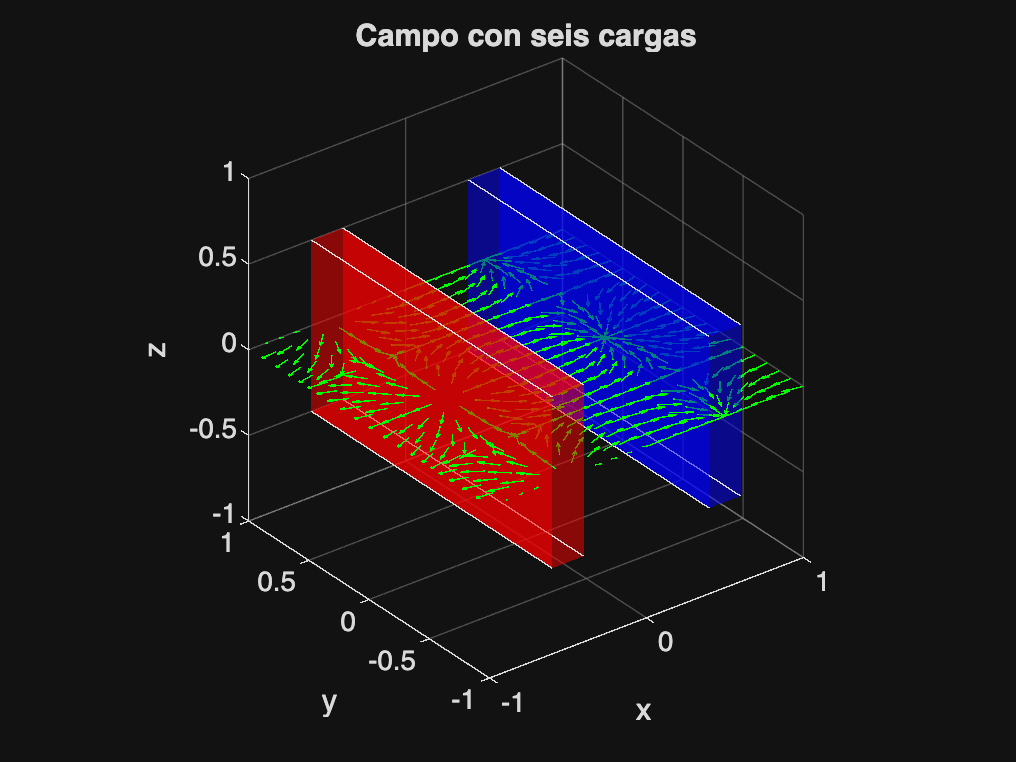

v = 0.5;

function vertices = crear_prisma(xc, yc, zc, ancho, largo, v)

    vertices = [
        -v*ancho+xc, -v*largo+yc, -v+zc;
        -v*ancho+xc,  v*largo+yc, -v+zc;
         v*ancho+xc,  v*largo+yc, -v+zc;
         v*ancho+xc, -v*largo+yc, -v+zc;
        -v*ancho+xc, -v*largo+yc,  v+zc;
        -v*ancho+xc,  v*largo+yc,  v+zc;
         v*ancho+xc,  v*largo+yc,  v+zc;
         v*ancho+xc, -v*largo+yc,  v+zc];
end 


% desplazamiento global
dx= -0.5;
dy = 0;
dz = 0;

% dimensiones de placas 
largo_roja = 3;
largo_azul = 3;
ancho = -0.2;


% posiciones de las placas en x 
x_roja = -d;
x_azul = d;


%caras de la caja 
caras = [1 2 3 4;
         2 6 7 3;
         4 3 7 8;
         1 5 8 4;
         1 2 6 5;
         5 6 7 8];

% placa roja 
vertices_roja = crear_prisma(x_roja, dy, dz, ancho, largo_roja, v);
% placa azul 
vertices_azul = crear_prisma(x_azul, dy, dz, ancho, largo_azul, v);

% dibujar placas
patch('Faces', caras,'Vertices', vertices_roja,'FaceColor','r','FaceAlpha',0.5);
patch('Faces', caras,'Vertices', vertices_azul,'FaceColor','b','FaceAlpha',0.5);

En esta parte del código, modelamos una placa cargada utilizando muchas cargas pequeñas distribuidas a lo largo de una región. Es básicamente una aproximación discreta de un sistema continuo, porque en la realidad la carga estaría distribuida de manera uniforme. Al dividirla en muchas cargas puntuales, podemos calcular el campo eléctrico sumando sus contribuciones individuales.

clc;
clear;

d = 1; 
ke = 9e+9; 
q1 = 1e-5; 
q2 = -1e-5;
lyp = 500; 
lyn = 500; 
dqp = q1 / lyp; 
dqn = q2 / lyn;

x_vals = linspace(-2, 2, 80);
y_vals = linspace(-2, 2, 80);
[x, y] = meshgrid(x_vals, y_vals);

%inicializar matrices 
Ex = zeros(size(x));
Ey = zeros(size(y));
V = zeros(size(x));

%coordenadas de las cargas 
y_val_p = linspace(-d,d,lyp);
y_val_n = linspace(-d/4,d/4,lyn);
x_val_p = ones(size(y_val_p)) * -0.25;
x_val_n = ones(size(y_val_n)) * 0.25;



Para calcular el campo eléctrico y el potencial, recorremos cada punto de la malla. En cada punto, sumamos la contribución de todas las cargas utilizando la ley de Coulomb. Este procedimiento se basa en el principio de superposición. 

for i = 1:length(x_vals)
    for j = 1:length(y_vals)
        px = x(i,j);   % punto donde mides
        py = y(i,j);
        for n = 1:lyp
            rx = px - x_val_p(n);  % vector desde carga → punto
            ry = py - y_val_p(n);
            r = sqrt(rx^2 + ry^2);
            Ex (i,j) = Ex(i,j) + ke * dqp * rx / r^3;
            Ey (i,j) = Ey(i,j) + ke * dqp * ry / r^3;
            V(i,j) = V(i,j) + (ke * dqp / r);
        end
        for m = 1:lyn 
            rx = px - x_val_n(m); 
            ry = py - y_val_n(m);
            r = sqrt(rx^2 + ry^2);
            Ex (i,j) = Ex(i,j) + ke * dqn * rx / r^3;
            Ey (i,j) = Ey(i,j) + ke * dqn * ry / r^3;
            V(i,j) = V(i,j) + (ke * dqn / r);
        end
    end
end



En esta parte se visualiza el campo eléctrico junto con las líneas equipotenciales. Las líneas equipotenciales representan regiones donde el potencial eléctrico es constante. Esto nos permite analizar la relación entre el campo eléctrico y el potencial. 

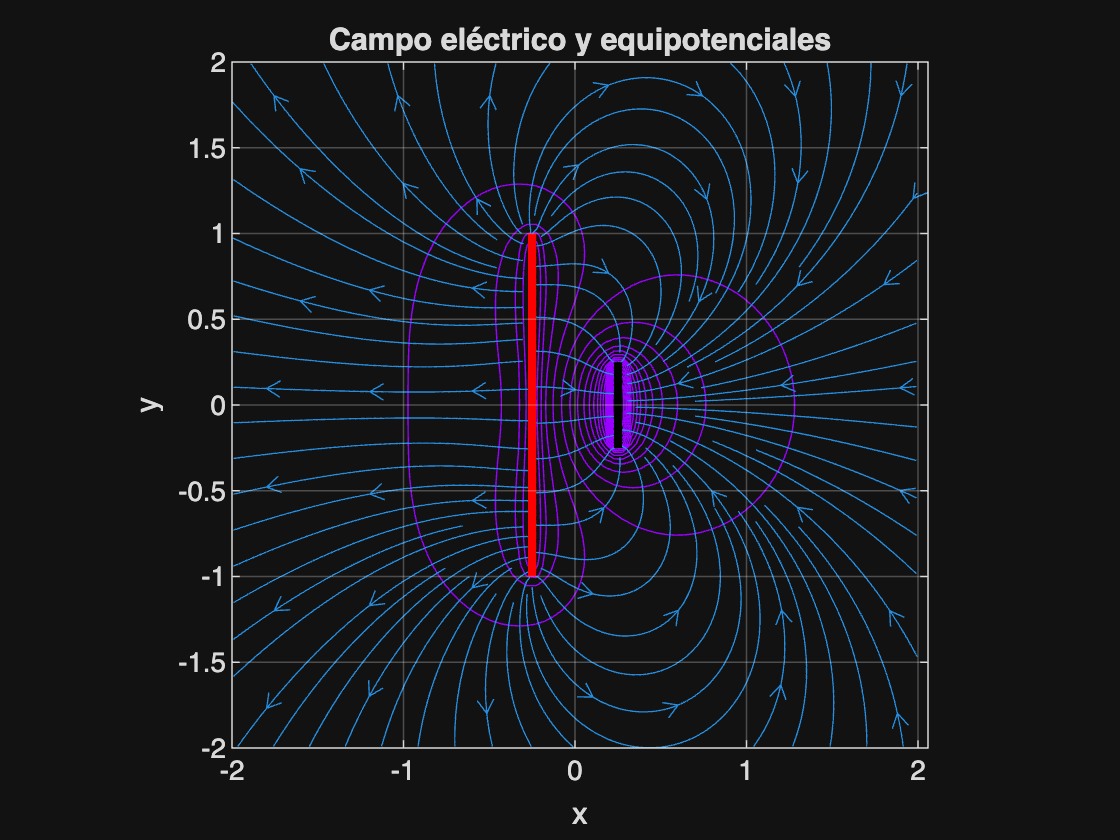

figure(1)
contour(x, y, V, 20, 'Color',[0.6 0 1])
hold on
streamslice(x, y, Ex, Ey)
plot(x_val_p, y_val_p, 'r', 'LineWidth', 3)
plot(x_val_n, y_val_n, 'k', 'LineWidth', 3)
xlabel('x')
ylabel('y')
title('Campo eléctrico y equipotenciales')
axis equal
grid on
hold off

En esta parte se simula el movimiento de partículas bajo la influencia del campo eléctrico. Se toman en cuenta diferentes tipos de partículas con propiedades distintas. El objetivo es analizar como se comportan y generar un conjunto de datos.


% ----- parámetros de simulación -----
nq = 40; %cantidad de glóbulos 
dt= 0.02;
dataset=zeros(nq,6);

function cell = randcell(h)
       cell = h*rand;
end 

figure(2);

ax_sim = axes; %objeto de ejes para mayor control
hold(ax_sim,'on');
title('Simulación de Separación para Dataset de IA');
xlabel('Posición X'); ylabel('Posición Y');
grid on;
axis(ax_sim, [-0.5 1.5 -2 1]);

% placas
plot(x_val_p, y_val_p, 'r', 'LineWidth', 3)
plot(x_val_n, y_val_n, 'k', 'LineWidth', 3)


Para cada partícula, calculamos su movimiento utilizando la segunda ley de Newton. Las fuerzas eléctricas se obtienen a partir del campo generado por las cargas. Usamos el método de Euler para actualizar su posición y velocidad conforme al tiempo. 

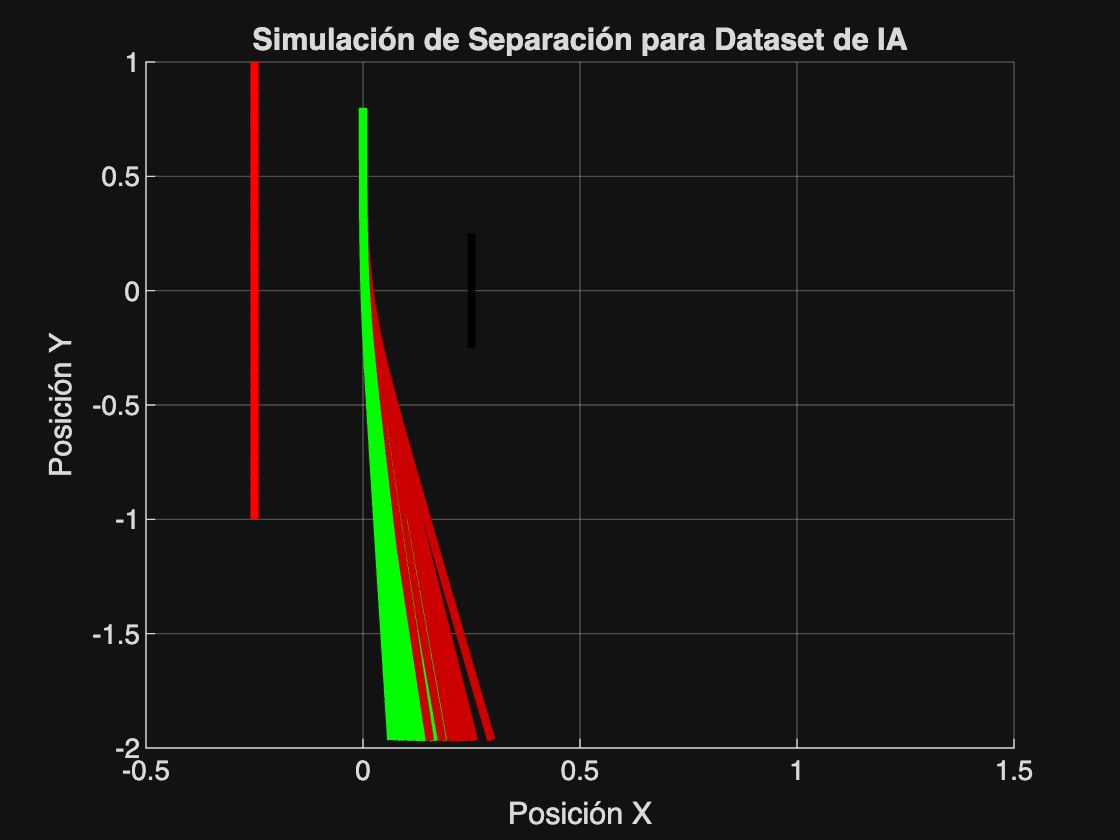

for q = 1:nq %ciclo sobre góbulos 
    % generamos de manera aleatoria la célula 
    if rand() > 0.5
        clase = 0; %SANO
        color = [0 1 0]; %color verde
        qE_base = 0.8e-6;
        m = 1;
    else 
        clase = 1; %INFECTADO CON MALARIA 
        color = [0.8,0,0]; %color rojo 
        qE_base = 1.4e-6;
        %volumen ocupado por el parásito
        vol_parasito = 0.1 + rand()*0.8;
        m = 1.0 + (vol_parasito*0.2);
    end 

    qE = qE_base + (randn()*0.25e-6);
    xe = 0;
    ye = 0.8;
    Vx = 0;
    Vy = -3;

    % variables para trackear 
    t_vuelo = 0;
    v_max = 0;

    path = animatedline('Color',color,'LineWidth',3);

    while ye > -2 && ye < 2 && xe > -2 && xe < 2 % area de movimiento 
        t_vuelo = t_vuelo + dt;
        addpoints(path,xe,ye);

        Fx = 0;
        Fy = 0;
        % solo tomamos en cuenta la influencia de la placa negativa 
        for k = 1:lyn
            rx = xe - x_val_n(k); 
            ry = ye - y_val_n(k);
            r = sqrt(rx^2 + ry^2);
            Fx = Fx + (ke * dqn * qE * rx / r^3); %COULOMB
            Fy = Fy + (ke * dqn * qE * ry / r^3);
        end 
        b = 0.4;
        F_arrastre_x = -b*Vx;

        % segunda ley de newton
        % Fx = Fx + F_arrastre_x;
        ax = Fx / m;
        ay = Fy / m;
        Vx = Vx + ax * dt;  % Euler 
        Vy = Vy + ay * dt; 
        xe = xe + Vx * dt;
        ye = ye + Vy * dt;
        
        v_inst = sqrt(Vx^2+Vy^2);
        if v_inst > v_max, v_max = v_inst; end 
    end
    dataset(q, :) = [qE, m, t_vuelo, v_max, xe, clase];
    drawnow limitrate 
end 


csvwrite('dataset_celulas.csv', dataset);

En la gráfica se puede ver cómo las partículas se desvían dependiendo de sus propiedades. Esta información se guarda en un dataset que se utiliza en la parte de la implementación de inteligencia artificial. 

En conclusión, este trabajo logramos ver cómo se comporta el campo eléctrico en diferentes configuraciones de cargas. Usamos el principio de superposición para sumar los efectos de cada carga y obtener el campo total. También aproximamos una placa continua usando muchas cargas pequeñas. Esto nos ayudó a entender mejor cómo la distribución de carga afecta el campo eléctrico. 